# Experiment with LSTMpathToEEG model(3 channels)

## Load data

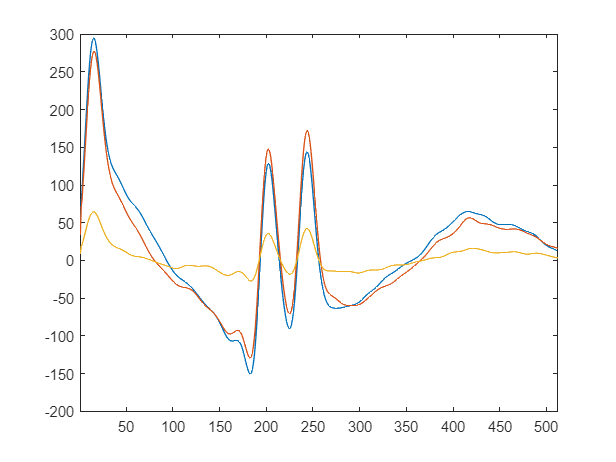

XTrain = load(fullfile('DataSet','HyperparameterSearch','Train','XSearchTrain.mat')).XSearchTrain;
YTrain = load(fullfile('DataSet','HyperparameterSearch','Train','YSearchTrain.mat')).YSearchTrain;

XTest = load(fullfile('DataSet','HyperparameterSearch','Test','XSearchTest.mat')).XSearchTest;
YTest = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};

figure;i = 1;
plot(XTrain{i}');
xlim([1 size(XTrain{i},2)]);

## Hyper-parameter search

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | miniBatchSize| learningrate |    numBlocks | numHiddenUni-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              | ts           |
|===================================================================================================================================|
|    1 | Best   |    0.080325 |      2322.8 |    0.080325 |    0.080325 |           10 |   0.00099648 |            7 |            6 |


|    2 | Accept |           1 |       208.9 |    0.080325 |    0.080325 |           48 |     0.045544 |            2 |          238 |
|    3 | Accept |    0.088113 |      101.97 |    0.080325 |    0.080325 |          128 |     0.017892 |            2 |           62 |
|    4 | Accept |    0.083718 |      176.62 |    0.080325 |    0.080325 |           91 |   0.00044183 |            1 |          243 |
|    5 | Accept |    0.087012 |       145.8 |    0.080325 |    0.080325 |          119 |     0.017603 |            2 |           93 |
|    6 | Accept |    0.087384 |      237.22 |    0.080325 |    0.080325 |          127 |   0.00066518 |            2 |          163 |
|    7 | Best   |    0.079706 |      116.21 |    0.079706 |    0.079706 |           49 |    0.0028873 |            1 |            5 |
|    8 | Accept |    0.079856 |      314.17 |    0.079706 |    0.079706 |           14 |     0.005769 |            1 |           13 |
|    9 | Accept |    0.082925 |      65.799 |    0.079706 |   

|   15 | Accept |           1 |      60.635 |    0.077113 |    0.077113 |          102 |     0.084658 |            1 |          125 |
|   16 | Accept |    0.083974 |      65.546 |    0.077113 |    0.077113 |          125 |    0.0065503 |            1 |           28 |
|   17 | Accept |    0.077641 |      171.73 |    0.077113 |    0.077113 |          127 |   0.00011508 |            1 |          237 |
|   18 | Accept |    0.089983 |      130.95 |    0.077113 |    0.077113 |          122 |    0.0059368 |            1 |          180 |
|   19 | Accept |    0.083241 |      81.469 |    0.077113 |    0.077113 |           89 |    0.0059739 |            1 |           56 |
|   20 | Accept |    0.088969 |      178.63 |    0.077113 |    0.077113 |           46 |    0.0017558 |            1 |          168 |
|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | Be

|   66 | Accept |    0.077321 |      3470.2 |    0.073211 |    0.073211 |          114 |    0.0025406 |            8 |          251 |
|   67 | Accept |    0.087506 |      320.75 |    0.073211 |    0.073211 |          127 |    0.0010212 |            8 |           26 |
|   68 | Accept |     0.08387 |      90.113 |    0.073211 |    0.073211 |          116 |      0.04008 |            1 |           45 |
|   69 | Accept |     0.07955 |      128.61 |    0.073211 |    0.073211 |          118 |   0.00020958 |            1 |          158 |
|   70 | Accept |    0.078518 |      111.06 |    0.073211 |    0.073211 |           99 |   0.00012388 |            1 |          102 |
|   71 | Accept |    0.084971 |      170.15 |    0.073211 |    0.073211 |           75 |    0.0036066 |            1 |          177 |
|   72 | Accept |    0.083588 |      338.25 |    0.073211 |    0.073211 |           20 |    0.0014177 |            1 |           36 |
|   73 | Accept |    0.079775 |      82.653 |    0.073211 |   

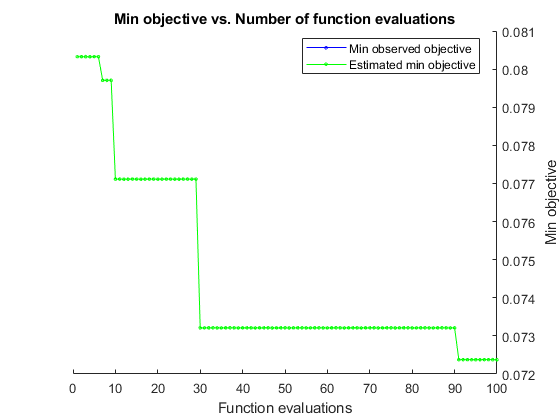


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 25217.5119 seconds
Total objective function evaluation time: 25163.3698

Best observed feasible point:
    miniBatchSize    learningrate    numBlocks    numHiddenUnits
    _____________    ____________    _________    ______________

         119          0.0078137          8              54      

Observed objective function value = 0.072376
Estimated objective function value = 0.072376
Function evaluation time = 410.4311

Best estimated feasible point (according to models):
    miniBatchSize    learningrate    numBlocks    numHiddenUnits
    _____________    ____________    

maxEpochs = 30;
optimVars = [
    %miniBatchSize,learningrate,numBlocks,numHiddenUnits;
    optimizableVariable('miniBatchSize',[8 128],'Type','integer')%[8 128]
    optimizableVariable('learningrate',[1e-4 1e-1],'Type','real',"Transform","log")
    optimizableVariable('numBlocks',[1 8],'Type','integer')%[1 5]
    optimizableVariable('numHiddenUnits',[1 256],'Type','integer')];

objectFunction = objectFunctionLSTM(trainDs, testDs,  maxEpochs);
    
% optimizer
BayesObject = bayesopt( objectFunction,             optimVars, ...
                        'MaxTime',                  24*60*60, ...
                        'Verbose',                  1,...
                        "UseParallel",              false,...
                        'IsObjectiveDeterministic', true, ...
                        'ParallelMethod',           "clipped-model-prediction",...
                        'MaxObjectiveEvaluations',  100,...
                        'ExplorationRatio',         0.6,...
                        'AcquisitionFunctionName', 'expected-improvement-per-second-plus');

optVars = bestPoint(BayesObject);



save("HyperparameterSearch\OptVars\LSTMoptVars.mat","optVars","-mat");


    % Evaluate and train the network with the optimal parameters
[valError,~,net, YPred, YTest] = BayesObject.ObjectiveFcn(optVars,1);

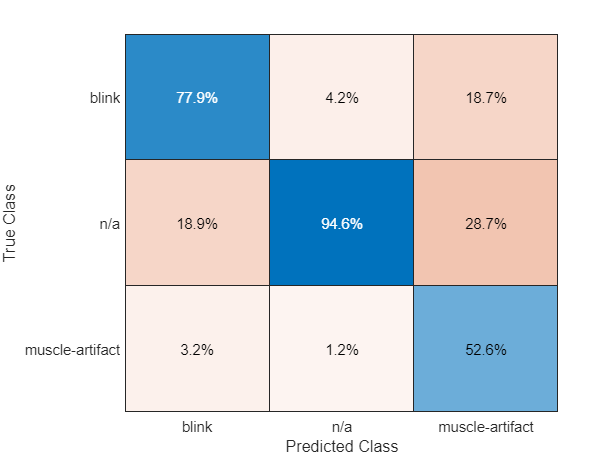

TX = {};
for k = 1:numel(testDs)
    TX{end+1} = testDs{k}{1};
end


TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(testDs{1})
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end

confusionchart(TY(:),Y(:),'Normalization','column-normalized');